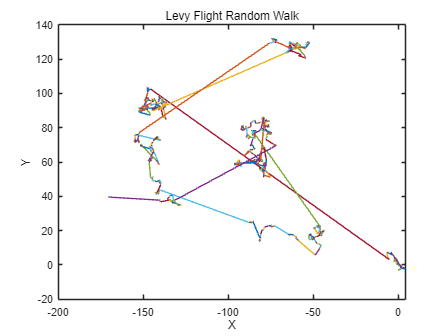

% 莱维轨迹
clear
close all
clc
% 设置参数
num_steps = 1000; % 游走步数
beta = 3/2; % 莱维指数，控制步长分布的形状

% 初始化位置数组
x = zeros(num_steps, 1);
y = zeros(num_steps, 1);

% 生成莱维分布的步长
step_lengths = levy(beta, num_steps);

% 生成随机[方向]
angles = 2 * pi * rand(num_steps, 1);

% 计算每一步的位置
for i = 2:num_steps
    x(i) = x(i-1) + step_lengths(i) * cos(angles(i));
    y(i) = y(i-1) + step_lengths(i) * sin(angles(i));
end

% 绘制游走图
figure
for i=1:num_steps-1
    plot(x(i:i+1), y(i:i+1));
    hold on
end
xlabel('X');
ylabel('Y');
title('Levy Flight Random Walk');


% 莱维分布[函数]

function step = levy(beta, num_steps)
    sigma_u = (gamma(1+beta)*sin(pi*beta/2) / (beta*gamma((1+beta)/2)*2^((beta-1)/2)))^(1/beta) ;
    sigma_v = 1;
    u = normrnd(0,sigma_u,num_steps,1) ;
    v = normrnd(0,sigma_v,num_steps,1) ;
    step = u./(abs(v).^(1/beta)) ;
end